#### Maciej Górnik

#### gr 1b, 402325

#### EAIiIB, AiR

# **Dostrajanie regulatorów PID**

## Cel ćwiczenia

Celem ćwiczenia jest zapoznanie się z praktycznymi, przemysłowymi metodami doboru nastaw regulatorów PID. 

Badane metody doboru nastaw:

- metoda Zieglera – Nicholsa w wersji „klasycznej” i przekaźnikowej (metoda Astroma- Hagglunda),

- metody oparte o parametry odpowiedzi skokowej obiektu,

- autotuning regulatora dostępny w środowisku SIMULINK.

## **Przebieg ćwiczenia**

W pierwszym kroku stworzono model w Simulinku pozwalający badać metody

### Model obiektu regulacji w Simulinku

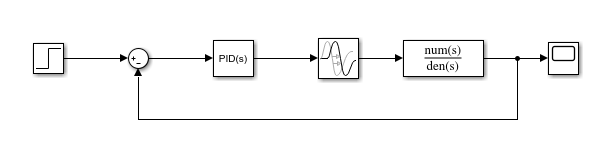

### Nastawy regulatorów wyznaczone z eksperymentu Zieglera - Nicholsa

Wartości parametrów Ki oraz Kd ustawiono na zero. Następnie zmieniano wartość Kp aż układ dotarł do granicy stabilności. Po znalezieniu granicy stabilności na wykresie sygnału wyjściowego wyznaczono okres oscylacji nietłumionych.

k = 1.18;
tau = 22;
T = 45;
r = 2.5;

for P = [1 3 3.3]
    figure;
    out = sim('Zad1.slx');
    u = out.u;
    l = append("P= ", string(P));
    plot(u.time,u.signals.values,'DisplayName',l)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    legend("Location","best");
    title("Sygnał wyjsciowy")
end

No system or file called 'Zad1.slx' found.

%Dla wartości 3.3 układ zaczyna oscylowac nie tłumiony
kr = 3.3;
t1 = 51.9;
t2 = 127.9;
Tosc = t2 - t1;


Zbadane wartości wynoszą:

kr = 3.3          - Kp na granicy stabilności

Tosc = 76       - okres oscylacji

Dla tych wartości wyznaczono nastawy regulatorów zgodnie z poniższymi wzorami:

regulator P: k = 0.5 kkr ,

regulator PI: k = 0.45 kkr , Ti = 0.85Tosc ,

regulator PID: k = 0.6 kkr , Ti = 0.5Tosc , Td = 0.12Tosc.

#### Regulator P:

Kp = 0.5 * kr = 1.65

kr= 3.3;
Tosc = 76;
Kp = 0.5 * kr;
figure;
out = sim('zad2.slx');
u = out.u;
l = append("Kp= ", string(Kp));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

#### Regulator PI:

Kp = 0.45 * kr = 1.485

Ti = 0.85 * Tosc = 64,6

kr= 3.3;
Tosc = 76;
Kp = 0.45 * kr;
Ti = 0.85 * Tosc;
figure;
out = sim('zad2_1.slx');
u = out.u;
l = append("Kp= ", string(Kp),", Ti= ", string(Ti));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

#### Regulator PID:

Kp = 0.6 * kr = 1.98

Ti = 0.5 * Tosc = 38

Td = 0.12 * Tosc = 9,12

kr= 3.3;
Tosc = 76;
Kp = 0.6 * kr;
Ti = 0.5 * Tosc;
Td = 0.12 * Tosc;
figure;
out = sim('zad2_2.slx');
u = out.u;
l = append("Kp= ", string(Kp),", Ti= ", string(Ti),", Td= ", string(Td));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

Analizując wykresy mozemy zauwazyć, że w regulatorze P nie udało sie osiągnąć wartości ustalonej równej 2.5. Regulatory PI oraz PID osiągneły ustaloną wartość, jednak regulator PID szybciej dotarł do niej dużo szybciej.

### Metoda Astroma – Hagglunda

W modelu układu regulacji zastąpiono regulator PID przekaźnikiem II położeniowym z histerezą równą zero oraz poziomami sygnału sterującego dla „0” i „1” równymi: poziom „0” wartość 1.0, poziom „1”: wartość 5.0. Natępnie wyznaczono amplitudę sterowania, oraz amplitudę sygnału wielkości regulowanej na wyjściu.Pozostałą część zadania rozwiązuje się już tak samo jak w przypadku metody  Zieglera - Nicholsa.

#### Model w Simulinku wykorzystany do metody Astroma – Hagglunda

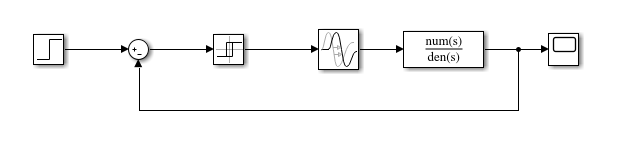

figure;
out = sim('astr_hagg.slx');
u = out.u;
l = append("Kp= ", string(Kp),", Ti= ", string(Ti),", Td= ", string(Td));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")
u0=1;
u1=5;
U = u1 - u0;

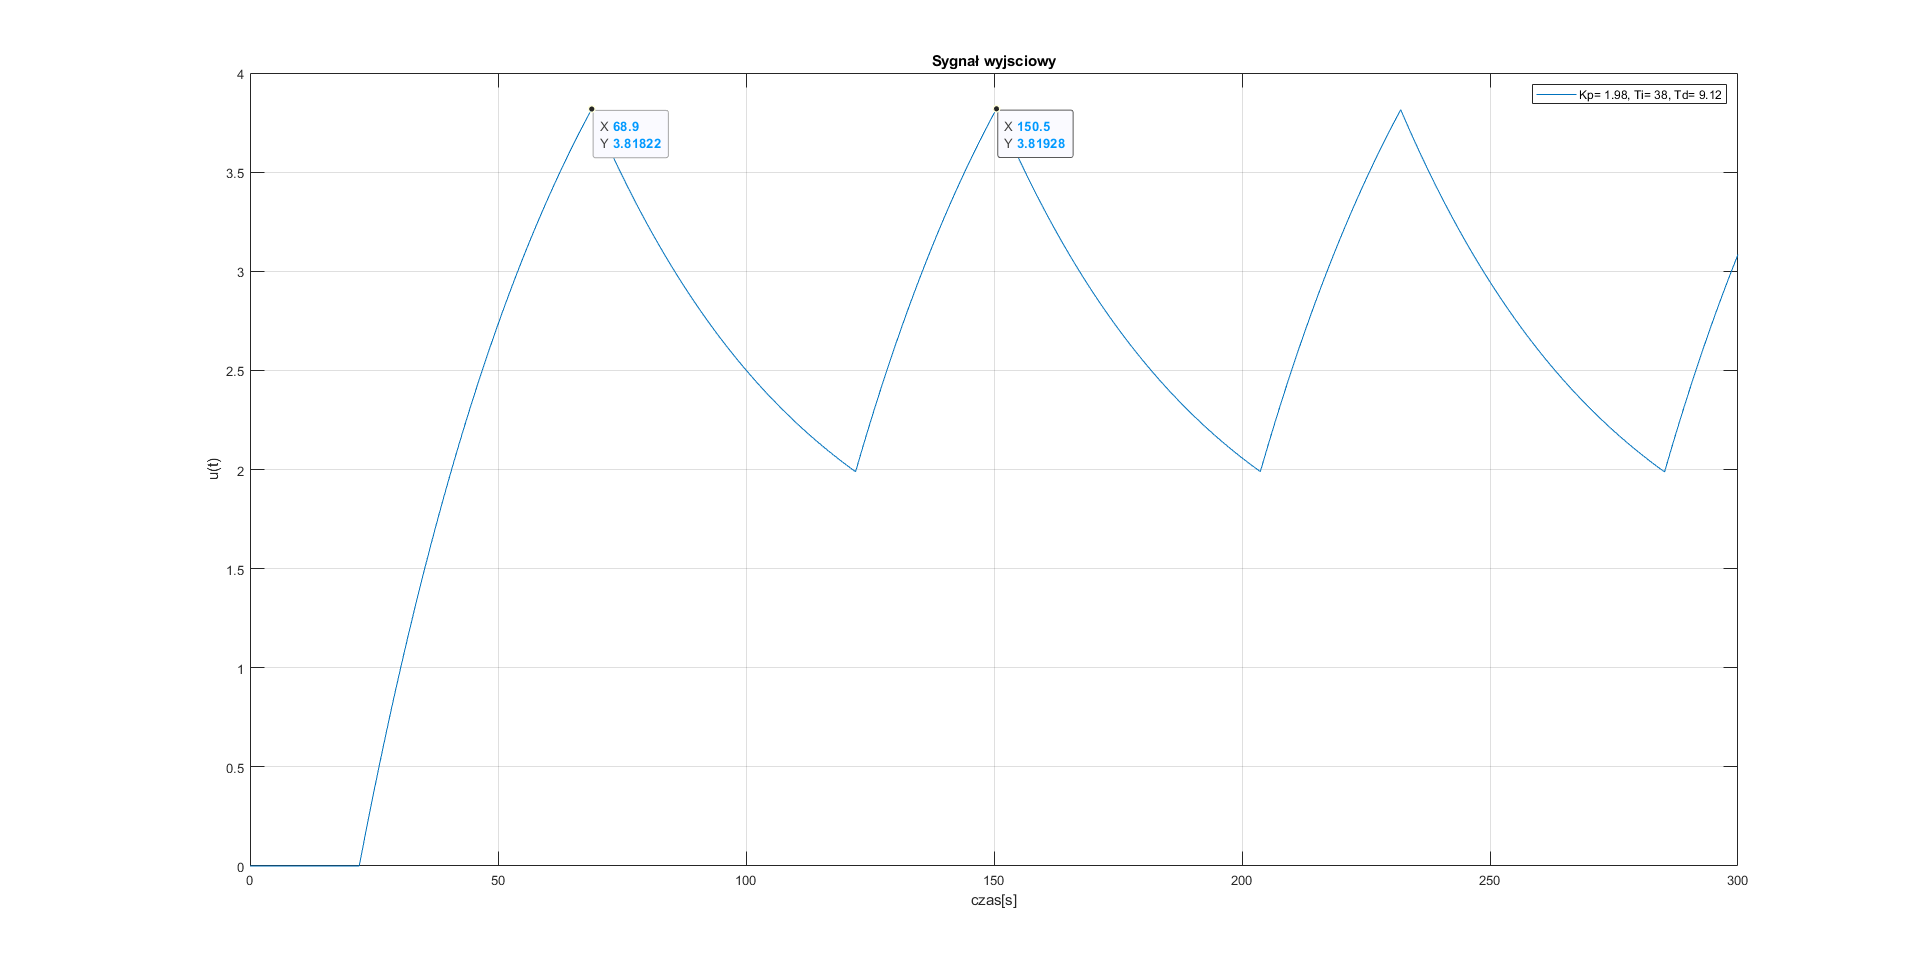

#### Wyznaczone parametry


$$\textrm{Tosc}=150\ldotp 5-68\ldotp 9=81\ldotp 6$$



$$A=1\ldotp 8$$



$$u=4$$



$$\textrm{kr}=\frac{4u}{\pi A}=2\ldotp 83$$


### Regulator P

t1 = 68.9;
t2 = 150.5;
Tosc = t2 - t1;
A = 1.8;
kr = 4*U/(pi*A);
Kp = 0.5 * kr;
figure;
out = sim('zad2.slx');
u = out.u;
l = append("Kp= ", string(Kp));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

### **Regulator PI**

t1 = 68.9;
t2 = 150.5;
Tosc = t2 - t1;
A = 1.8;
kr = 4*U/(pi*A);
Kp = 0.45 * kr;
Ti = 0.85 * Tosc;
figure;
out = sim('zad2_1.slx');
u = out.u;
l = append("Kp= ", string(Kp),", Ti= ", string(Ti));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

### Regulator PID

t1 = 68.9;
t2 = 150.5;
Tosc = t2 - t1;
A = 1.8;
kr = 4*U/(pi*A);
Kp = 0.6 * kr;
Ti = 0.5 * Tosc;
Td = 0.12 * Tosc;
figure;
out = sim('zad2_2.slx');
u = out.u;
l = append("Kp= ", string(Kp),", Ti= ", string(Ti),", Td= ", string(Td));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

Metoda Astroma – Hagglunda wydaje się byś dużo bezpieczniejsza od matody Zieglera - Nicholsa. Wyniki obu metod dają porównywalne wartości.

### Metody oparte o parametry odpowiedzi skokowej obiektu

#### Przy założeniu przeregulowania 20% oraz minimalnego czasu regulacji

𝑘𝑟=0.95∗𝑇*/(k*∗𝑡𝑎𝑢 )

𝑇𝑖=2.4∗𝑡𝑎𝑢 

𝑇𝑑=0.4∗𝑡𝑎𝑢

k = 1.18;
tau = 22;
T = 45;

Kp = 0.95*T/(k*tau);
Ti = 2.4*tau;
Td = 0.4*tau;
figure;
out = sim('zad2_2.slx');
u = out.u;
l = append("Kp= ", string(Kp),", Ti= ", string(Ti),", Td= ", string(Td));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

#### Przy założeniu minimum całki kwadratowej uchybu $\int_0^{\infty } \varepsilon^2 \left(t\right)\textrm{dt}$

𝑘𝑟=1.4∗𝑇/(𝑘∗𝑡𝑎𝑢)

𝑇𝑖=1.3∗𝑡𝑎𝑢 

𝑇𝑑=0.5∗𝑡𝑎𝑢

k = 1.18;
tau = 22;
T = 45;

Kp = 1.4*T/(k*tau);
Ti = 1.3*tau;
Td = 0.5*tau;

figure;
out = sim('zad2_2.slx');
u = out.u;
l = append("Kp= ", string(Kp),", Ti= ", string(Ti),", Td= ", string(Td));
plot(u.time,u.signals.values,'DisplayName',l)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

figure;
out = sim('Autotune.slx');
u = out.u;
plot(u.time,u.signals.values)
grid
xlabel('czas[s]')
ylabel('u(t)')
legend("Location","northeast");
title("Sygnał wyjsciowy")

Metoda przy założeniu przeregulowania 20% oraz minimalnego czasu regulacji, okazała sie byc bardzo skuteczna układ dotarł do ustalonej wartości w krótkim czasie. W metodzie przy założeniu minimum całki kwadratowej uchybu na wyjsciu widoczne były duże oscylacje jednak układ nadal docierał do ustalonej wartości, ale w dłuższym czasie niz w przypdku poprzednich metod.

### Użycie funkcji „Autotune” dostępnej w środowisku SIMULINK

### Regulator P 

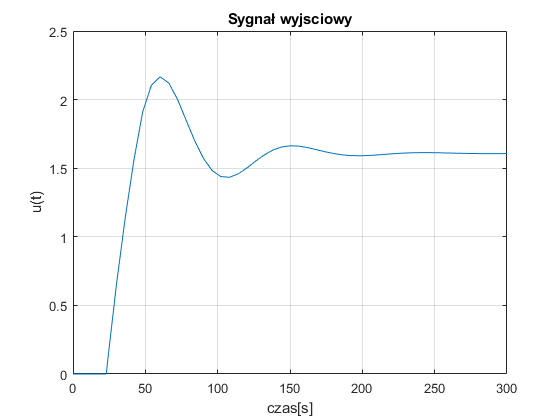

Rys. 1. Wykres zależności wartości regulowanej od czasu dla regulatora P (czas regulacji 60s)

### Regulator PI

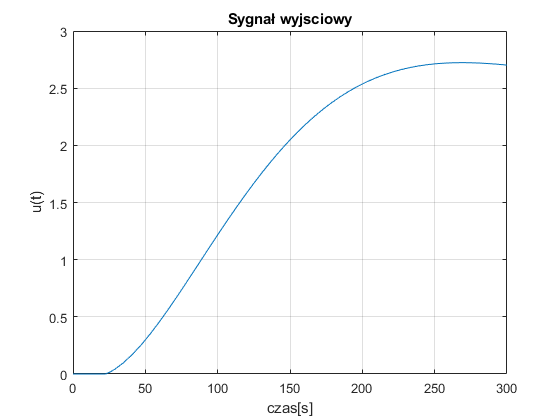

Rys. 2. Wykres zależności wartości regulowanej od czasu dla regulatora PI (czas regulacji 200s, przeregulowanie 0.6)

### Regulator PD

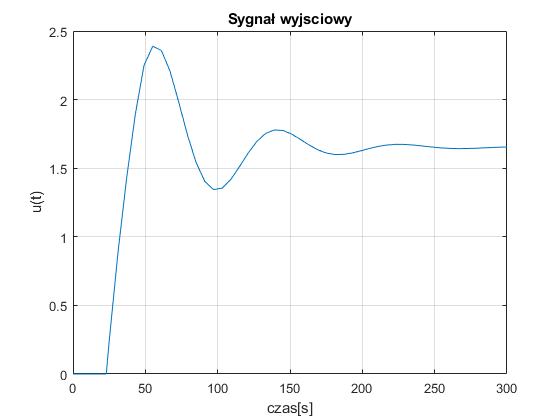

Rys. 3. Wykres zależności wartości regulowanej od czasu dla regulatora PD (czas regulacji 50s, przeregulowanie 0.7)

### Regulator PID

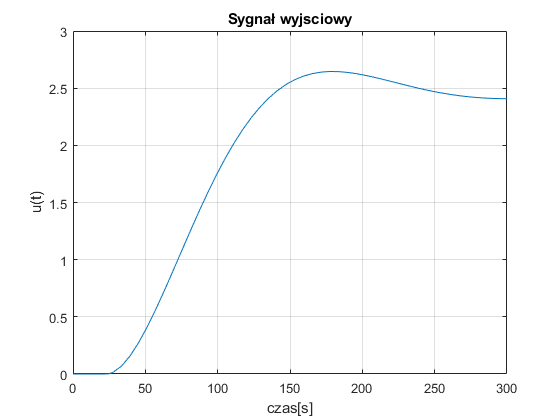

Rys. 5. Wykres zależności wartości regulowanej od czasu dla regulatora PID (czas regulacji 150s, przeregulowanie 0.45)

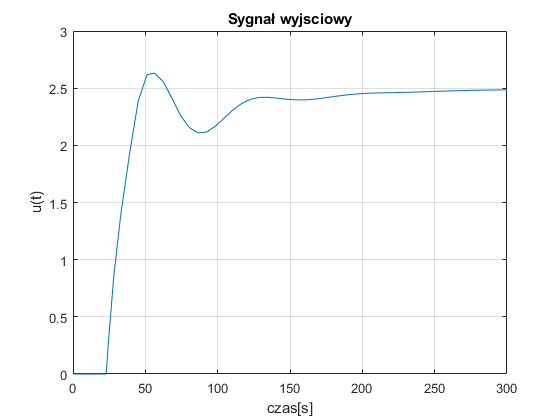

Rys. 5. Wykres zależności wartości regulowanej od czasu dla regulatora PID (czas regulacji 60s, przeregulowanie 0.7)

Funkcja Autotune pozwala na łatwe i wygodne dostrajanie regulatorów. W tej funkcji zmieniając suwakiem wartości *Response Time* i *Transistent Behavior* zmieniamy parametry nastawów. 

## Wnioski

Wykonane ćwiczenia pozwoliły na poznanie metod regulacji i dostrajania nastawów regulatorów P, PI, PD i PID. 